# **半波振子天线的仿真（天线工具箱仿真计算）**

**        与**[**上一小节**](matlab:open('./G5_Dipole_Antenna_Antenna_Toolbox.mlx'))**类似，本小节使用天线工具箱仿真半波振子天线。**

- **可使用dipoleCylindrical函数创建半波振子天线，并将天线总体长度定义为波长的一半**

clc
clear
freq=70e6;
c=3e8;
lambda=c/freq

lambda = 4.2857

L=lambda/2;
W=0.05;
h=dipoleCylindrical('Length',L,'Radius',W);                   
figure                                       %显示天线特性并观察天线结构的变化
show(h);
title('半波振子天线');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真方向图**

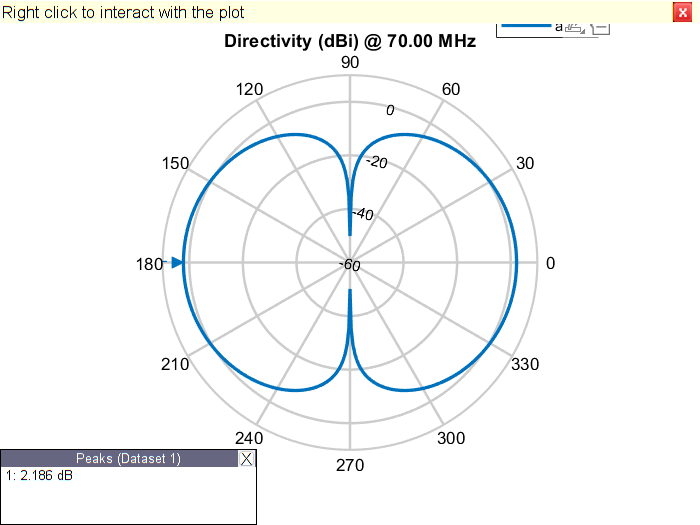

ele=-90:5:90;                                         %方位角
azi=-180:1:180;                                       %仰角
vertSlice=patternElevation(h,freq,0,'Elevation',ele); %使用patternElevation函数创建2D图
theta=90-ele;
figure
patternElevation(h,freq);           %方位角为0°的仰角方向图

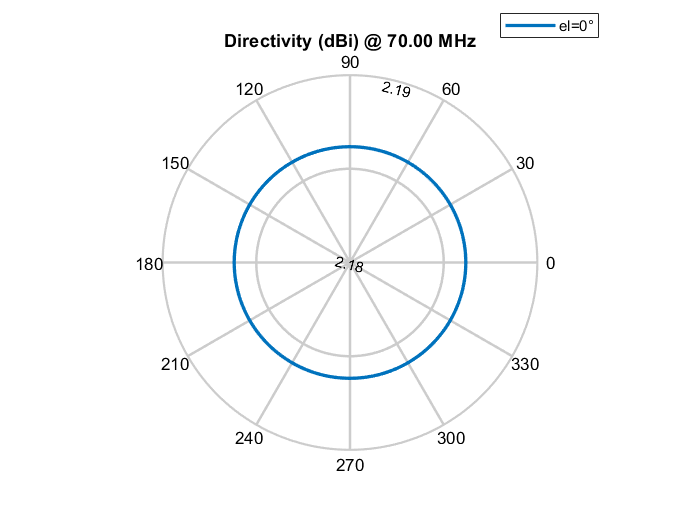

figure
patternAzimuth(h,freq,0,'Azimuth',azi);               %仰角为0°的方位角方向图

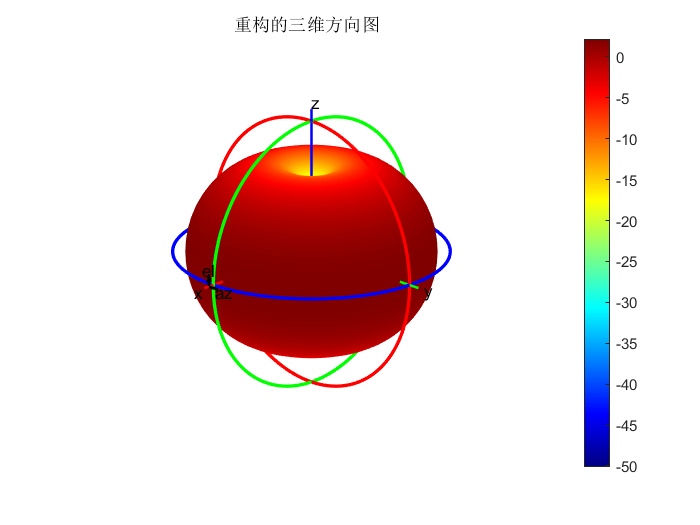

figure
patternFromSlices(vertSlice,theta);
title('重构的三维方向图');
set(gcf,'Visible','on');   	    %强制图片弹出显示

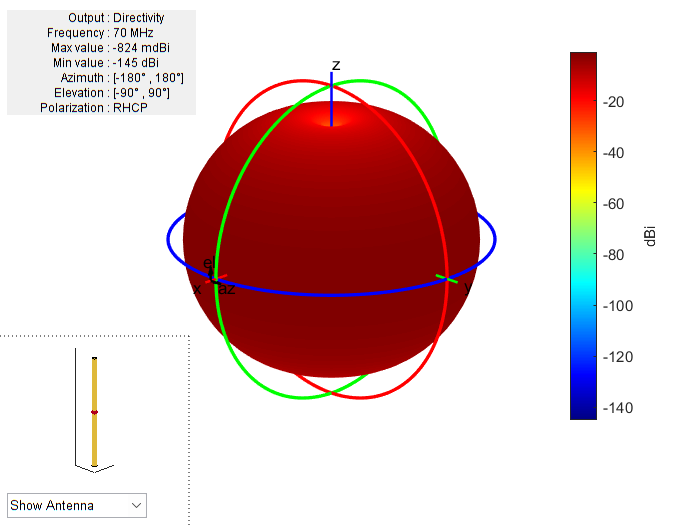

Directivity=pattern(h,freq,0,90);                %使用pattern函数还可以计算天线的方向性系数
[E,H]=EHfields(h,freq,[0;0;1]);                  %使用EHfields函数计算天线在空间一点的电场和磁场的x,y,z分量
figure
pattern(h,freq,'Polarization','RHCP');           %使用pattern函数中的极化属性绘制天线的极化方式，反射天线和接收天线应具有相同的极化方式

- **仿真输入阻抗**

figure
impedance(h,0.9*freq:freq/100:1.1*freq);
title('半波振子天线的输入阻抗');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真计算反射系数S11**

S=sparameters(h,0.9*freq:freq/100:1.1*freq,21);               %用sparameters函数计算天线的反射系数S11
figure
rfplot(S);
title('半波振子天线的反射系数');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真计算回波损耗**

figure
returnLoss(h,0.9*freq:freq/100:1.1*freq,21);                  %用returnLoss函数计算并绘制天线的回波损耗
title('半波振子天线的回波损耗');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真计算驻波比**

figure
vswr(h,0.97*freq:freq/100:1.03*freq,21);                        %用vswr函数计算并绘制天线的电压驻波比
title('半波振子天线的电压驻波比');
set(gcf,'Visible','on');   	    %强制图片弹出显示

## **参考文献：**

        **[1] **[**https://ww2.mathworks.cn/help/antenna/ref/dipolecylindrical.html**](https://ww2.mathworks.cn/help/antenna/ref/dipolecylindrical.html)